clear;
clc;
close all;

% Constantes (SSO)
mu = 3.986004418e14;
J2 =   1.082635854e-3;
J3 = - 2.532435346e-6;
R = 6378.137e3;
a = R + 1400e3;
e = 0;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(90);
Omega   = deg2rad(0);
omega   = deg2rad(0);
theta_0 = deg2rad(0);

% Lapso temporal
t = 0:1:4*pi/n;

% Condiciones iniciales
[posECI, velECI] = OE2ECI(mu, a, e, INC, Omega, omega, theta_0);
x0I = posECI(1);
y0I = posECI(2);
z0I = posECI(3);
dx0I = velECI(1);
dy0I = velECI(2);
dz0I = velECI(3);
x0   = 0;
y0   = 0;
z0   = 0;
dx0  = 0;
dy0  = 0;
dz0  = 0;

% Solución analítica
X0 = [x0, y0, z0, dx0, dy0, dz0];
[xB, yB, zB, xdotB, ydotB, zdotB] = computeGeneralSolution(J2, J3, R, a, e, INC, Omega, omega, theta_0, X0, n, t);
AM  = [xB', yB', zB', xdotB', ydotB', zdotB'];

% Resolución
X0I = [x0I, y0I, z0I, dx0I, dy0I, dz0I];
opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);

[~, dXdt_Kepler] = ode113(@(t, X) odeKepler(X, mu), t, X0I, opts);
dXdt = cowellZonals(X0I, t, mu, R, [J2; J3; 0; 0; 0], opts);

FAM = AM + dXdt_Kepler;

rFAM = FAM(:, 1:3);
rX   = dXdt(:, 1:3);

error          = norm(rFAM(end, :) - rX(end, :))

error = 288.8750

error_relativo = error / norm(rX(end, :)) * 100

error_relativo = 0.0037

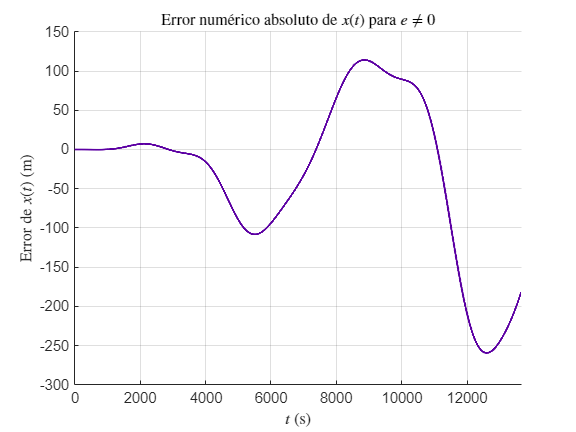


% Comparación
plotNumericError(FAM(:,1), dXdt(:,1), t, 'Error num\''erico absoluto de $x(t)$ para $e \neq 0$', ...
    '', '$t$ (s)', 'Error de $x(t)$ (m)', '#5C00A3');

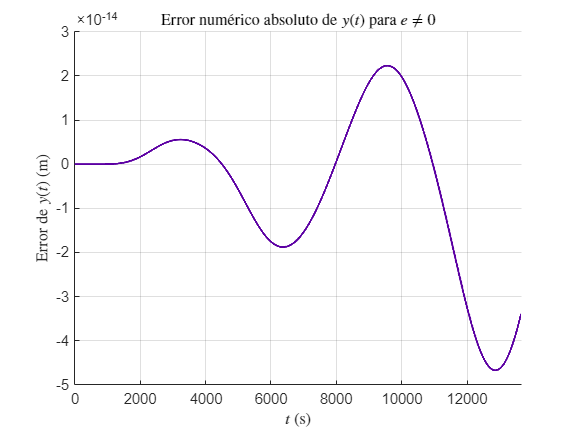

plotNumericError(FAM(:,2), dXdt(:,2), t, 'Error num\''erico absoluto de $y(t)$ para $e \neq 0$', ...
    '', '$t$ (s)', 'Error de $y(t)$ (m)', '#5C00A3');

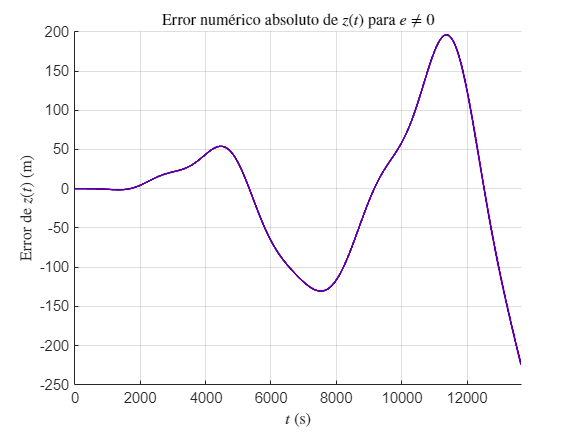

plotNumericError(FAM(:,3), dXdt(:,3), t, 'Error num\''erico absoluto de $z(t)$ para $e \neq 0$', ...
    '', '$t$ (s)', 'Error de $z(t)$ (m)', '#5C00A3');

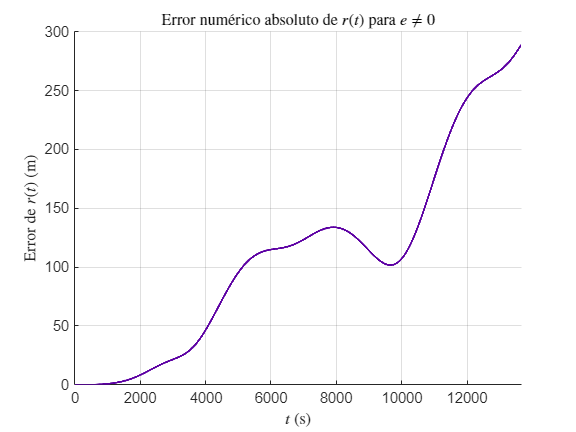


plotNumericErrorNorm(rFAM, rX, t, 'Error num\''erico absoluto de $r(t)$ para $e \neq 0$', ...
    '', '$t$ (s)', 'Error de $r(t)$ (m)', '#5C00A3');

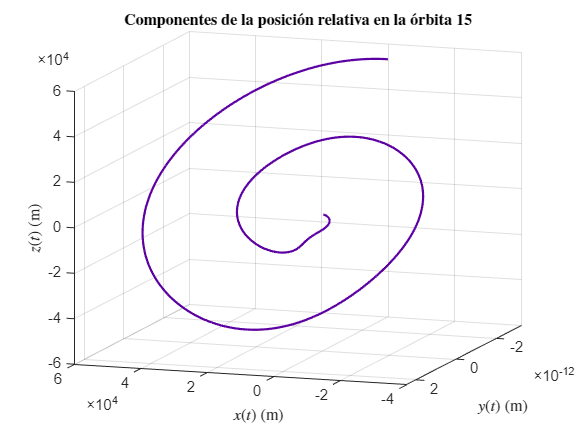


if ~exist('figuras', 'dir')
    mkdir('figuras');
end
plot3D({xB, yB, zB}, [-161 13], ...
    '\bf{Componentes de la posici\''on relativa en la \''orbita 15}', ...
    {'$x(t)$ (m)', '$y(t)$ (m)', '$z(t)$ (m)'}, '#5C00A3');
print(gcf, '-dpng', fullfile('figuras', '3D.png'));